clear all 
close all 
clc

% choose a MCS 
%%parametter 

addEndFileName = "use_case_3";
enableTraces = false;
enableLoadingBar = false;
numFrameSimulation =100;%in ms
technology = "NR-V2X";
bitRate = 20; %in Mbit/s
MCS = 9;
speed(1) = 250;  %in km/h
speed(2) = 150; %in km/h
switch technology 
    case("NR-V2X")
        
        ChannelBandwidth=20e6 ;
        CarrierFrequency=5.900e9;
        SubcarrierSpacing=30000 ; 
        
    case("LTE-V2X") 
    case("C-V2X")
    

end




## Node creation

Défine the number of nodes 

numgnb = 1; % Number of gnb
numUEs = 2; % Number of UEs



%Position of nodes 
gnbPositions = [
    0, 0, 5
    
];

uePositions = [
    100, 0, 3
    100, 0, 3
];


% Initialize the simulator
networkSimulator = wirelessNetworkSimulator.init;

% Create gNB nodes with their parameters
gnb = nrGNB(Position=gnbPositions, ...
    TransmitPower=23, ...
    ChannelBandwidth=ChannelBandwidth, ...
    NumResourceBlocks = 51, ...
    CarrierFrequency=CarrierFrequency, ...
    SubcarrierSpacing=SubcarrierSpacing, ...
    PHYAbstractionMethod="none", ...
    NumTransmitAntennas=1, ...
    ReceiveGain=9);

%LinkAdaptationConfigDL = struct(InitialOffset  = 3, StepUp = 0.27, StepDown =0.03);
% MUMIMOConfigDL = struct(MaxNumUsersPaired =4,MinNumRBs =2,MinCQI =10,SemiOrthogonalityFactor =0.9);
configureScheduler(gnb,"FixedMCSIndexDL",MCS) 

%%%%%%%%%%%
%gnb.CSIRSConfiguration.CSIRSPeriod = [4, 1] ;
%gnb.CSIRSConfiguration.SubcarrierLocations = [0,3,7,10];
%%%%%%%%%%%%%% 


% Create the UE nodes with their parameter
ues = nrUE(Position=uePositions, PHYAbstractionMethod="none",NoiseFigure=9,NumReceiveAntennas=1,NumTransmitAntennas=1,ReceiveGain=3);


%ue.Name = "consist";
%gnb.Name = "anthenna" ;
%ues.Velocity = [speed(1)/3.6 0 0];
% configure up link power 
%configureULPowerControl(gnb,PoPUSCH=23,Alpha=0.4);

% Add custom channel models to the simulator
addChannelModel(networkSimulator, @channel);

% Connect UE to gnb

for j = 1:numUEs
    connectUE(gnb, ues(j));
end

% Define and add trafic
for j = 1:numUEs
    traffic(j) = networkTrafficVideoConference(FrameInterval=ceil(40/bitRate),FrameSizeMethod = "FixedSize"); 
end

for j = 1:numUEs
    addTrafficSource(gnb, traffic(j), DestinationNode=ues(j));
end
% adding nodes to the simulator 
addNodes(networkSimulator,gnb)
for j = 1:numUEs
    addNodes(networkSimulator,ues(j))
end


## Channel Creation

environement = "Open_space";

% Calculate the total number of nodes by adding the number of gnb and UEs
numNodes=length(gnb)+length(ues);

% Retrieve OFDM information based on the number of resource blocks and subcarrier spacing
waveformInfo = nrOFDMInfo(gnb.NumResourceBlocks,gnb.SubcarrierSpacing/1e3);
channelFilteringFlag = strcmp(gnb.PHYAbstractionMethod,"none");

% Initialize the TDL channel cell array and the path filter cell array
channelInfo.TDLChannels = cell(numNodes,numNodes);
channelInfo.PathFilter = cell(numNodes,numNodes);
channelInfo.MaxChannelDelayMatrix = zeros(numNodes,numNodes);

% choising environement type 
switch environement
    case("Open_space")
        delays = [0, 0.3e-6, 0.6e-6]; 
        gains = [0, -12.9, -22.9]; 

    case("Hilly_near_region")
        delays = [0, 97.65e-9, 216.79e-9]; 
        gains = [0, -6.77, -15.04]; 

    case("Hilly_far_region")
        delays = [0, 78.12e-9, 175.77e-9, 234.36e-9]; 
        gains = [0, -3.23, -7.79, -16.55]; 

    case("Tunnel")
    case("Cutting")
        delays = [0, 0.24e-6, 0.36e-6, 0.46e-6, 1.18e-6]; 
        gains = [0, -8.6, -12.12,-8.5, -12.83 ]; 

    case("Viaduct")
        delays = [0, 106.5e-9, 428.4e-9]; 
        gains = [0, -22.95, -39.6]; 
end

% set up doppler shift
for j = 1:numUEs
   speed(j) = speed(j)/3.6 ;
end

delayProfile = 'custom'; 
NumTransmitAntennas = 1;
NumReceiveAntennas = 1;
maxDopplerShift = zeros(1,numUEs);
for j = 1:numUEs
    maxDopplerShift(j) = speed(j)/physconst('LightSpeed')*CarrierFrequency ;
end

%Kfactor = 5 ; for viaduct 

for i=1:length(ues)
    % Create a TDL channel model 
    channelInfo.TDLChannels{gnb.ID, ues(i).ID} = nrTDLChannel ;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.DelayProfile = delayProfile;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.FadingDistribution ="Rician";
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.PathDelays = delays;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.AveragePathGains = gains ;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.NumReceiveAntennas =NumReceiveAntennas;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.NumTransmitAntennas =NumTransmitAntennas;
   % channelInfo.TDLChannels{gnb.ID, ues(i).ID}.MIMOCorrelation = "Medium";
   % channelInfo.TDLChannels{gnb.ID, ues(i).ID}.NormalizePathGains=false;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.ChannelFiltering = true; %false if abstract PHY
    %channelInfo.TDLChannels{gnb.ID, ues(i).ID}.KFactorFirstTap = Kfactor ; 
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.MaximumDopplerShift =maxDopplerShift(i) ;
    channelInfo.TDLChannels{gnb.ID, ues(i).ID}.SampleRate = waveformInfo.SampleRate;
    
    channelInfo.TDLChannels{ues(i).ID,gnb.ID} = channelInfo.TDLChannels{gnb.ID, ues(i).ID} ;

    % Retrieve the channel information
    chInfo = info(channelInfo.TDLChannels{gnb.ID, ues(i).ID});
    % Calculate the maximum channel delay and update the delay matrix
    channelInfo.MaxChannelDelayMatrix(gnb.ID, ues(i).ID) = ceil(max(chInfo.PathDelays*waveformInfo.SampleRate)) + chInfo.ChannelFilterDelay;
    channelInfo.PathFilter{gnb.ID,ues(i).ID} = getPathFilters(channelInfo.TDLChannels{gnb.ID,ues(i).ID}).';

    channelInfo.MaxChannelDelayMatrix(ues(i).ID,gnb.ID ) = channelInfo.MaxChannelDelayMatrix(gnb.ID, ues(i).ID);
    channelInfo.PathFilter{ues(i).ID,gnb.ID} = channelInfo.PathFilter{gnb.ID,ues(i).ID} ;
end
getSetChannelModel(channelInfo);

## Traces

cellToAnalyze = [2];
linkDir = 0; % Indicates DL
if enableTraces
    simPhyLogger = cell(numNodes,1);

    for cellIdx = 1:numUEs
        % Create an object for PHY layer traces logging
        simPhyLogger{cellIdx} = helperNRPhyLogger(numFrameSimulation,gnb, ues);
    end

    simulationLogFile = "simulationLogs"; % For logging the simulation traces

    if enableTraces
        numMetricPlotUpdates = numFrameSimulation;

        showSchedulerMetrics = true;
        showPhyMetrics = true;
        showCDFMetrics = false;
    
        metricsVisualizer = helperNRMetricsVisualizer(gnb,ues, ...
        CellOfInterest=cellToAnalyze,NumMetricsSteps=numMetricPlotUpdates, ...
        PlotSchedulerMetrics=showSchedulerMetrics,PlotPhyMetrics=showPhyMetrics, ...
        PlotCDFMetrics = showCDFMetrics,LinkDirection=linkDir);
    end
end

## Initialisation save folder and save file

simuFolder = 'simuFolder';
simuData = technology +"_"+ environement +"_"+ addEndFileName;
folderPath = fullfile(simuFolder,simuData)

folderPath = "simuFolder\NR-V2X_Open_space_use_case_1"

if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

logfile = fullfile(folderPath, 'logfile.txt');


## Simulation

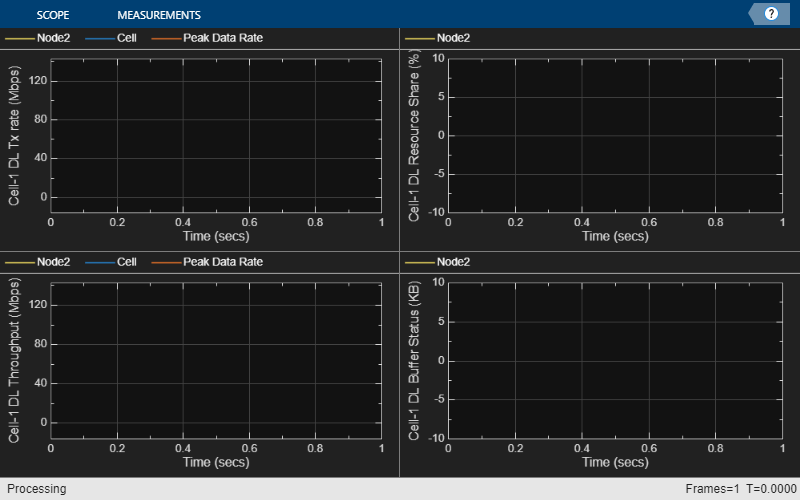

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 2-by-1.

Error in helperNRMetricsVisualizer/plotLiveMACMetrics (line 586)
                txRate(:, obj.DownlinkIdx) = (txBytes - obj.MACTxBytes(:, obj.DownlinkIdx))* 8 / (obj.MetricsStepDuration * 1000);

Error in helperNRMetricsVisualizer/plotLiveMetrics (

simulationTime = numFrameSimulation*1e-2;

%establishing schedule action during simulation 
global data
packetTime =  [] ;
nbreceive = zeros(1,numUEs);


data = struct(ues = ues,gnb = gnb, Simulator=networkSimulator,packet = packetTime,simulationTime =simulationTime,numUEs = numUEs,nbsend = 0, nbreceive = nbreceive);
scheduleAction(networkSimulator,@setinfo,data,0,0); %wake up setinfo when current time simulation is updated 

if enableLoadingBar
    scheduleAction(networkSimulator,@loadingBar,data,0,0.001);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%start of simulation 
run(networkSimulator,simulationTime);

cprintf('green', '\nSimulation is over\r\n');
diary(logfile);

## Display data analysis

%analysis of data
analysedData = dataAnalysis(data);

if enableTraces
    displayPerformanceIndicators(metricsVisualizer)
end
diary off;

## Save Log

%save of data in files and folders 
data_path = fullfile(folderPath, 'data.mat');
analysedData_path = fullfile(folderPath, simuData+"_"+ 'analysedData.mat');
%save(data_path, 'data');
save(analysedData_path, 'analysedData');

if enableTraces
    % Obtain the logs
    simulationLogs = cell(numUEs, 1);
    for cellIdx = 1:numUEs
        if gnb.DuplexMode == "FDD"
            logInfo = struct(NCellID=[],DLTimeStepLogs=[], ...
                SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
            %logInfo.DLTimeStepLogs = getSchedulingLogs(simSchedulingLogger{cellIdx});
        else % TDD
            logInfo = struct(NCellID=[],TimeStepLogs=[], ...
                SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
           % logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger{cellIdx});
        end
        logInfo.NCellID = gnb.ID;
        % Obtain the scheduling assignments log
       % logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger{cellIdx});
        % Obtain the Phy reception logs
        logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger{cellIdx});
        simulationLogs{cellIdx} = logInfo;
    end
    % Save simulation logs in a MAT-file
    simulationLogFile = fullfile(folderPath,simulationLogFile);
    save(simulationLogFile,"simulationLogs")
end



